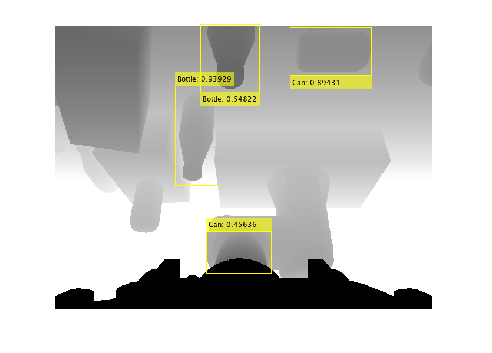

addpath('C:\Users\roboime\Downloads\');
load('C:\Users\roboime\Downloads\Depth_Detector.mat','shapeDetector');
imTest = imread('Teste2.jpeg');
[dbox,dscore,dlabel] = detect(shapeDetector,imTest);

labelsWithScores = string(dlabel) + ": " + string(dscore);
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);